# Kalman Filter for Rocket

A Kalman filter is a useful tool for combining both measurements and modeling into a single refined state estimate technique. Running a Kalman filter on the rocket could be useful for more accurately detecting apogee as well as getting a better idea of how high the rocket goes.

The first thing to do is to make some fake sensor data. This was done by solving a second order equation of motion of an object. Note that this model considers air resistance. The output of this model is displayed below.

%run simple model to generate fake positoin data for rocket
dt = 0.1;
[T, D] = altitude_model(dt);  %dt

Unrecognized function or variable 'altitude_model'.

For the filter we will first only consider the z position since this can be measured with a barometer chip. We will also use the vertical acceleration which can be measured with an accelerometer(?). To make the fake sensor data, we will add some normally distributed noise with a standard deviation of 10.

The fake sensor data is plotted below.

true_state = [D(:,3), D(:,6)]; %extract z position and velocity data
%create normal distributed noise
sigma = 10;
noise = sigma*randn(size(true_state));
%add noise to data
noise_state = true_state + noise;

%plotting
figure(1)
clf
set(figure(1), "Position", [0 0 1000, 400])
subplot(1,2,1)
hold on
plot(T, true_state(:,1))
plot(T, noise_state(:,1))
hold off
xlabel("Time (s)")
ylabel("Hight (m)")


subplot(1,2,2)
hold on
plot(T, true_state(:,2))
plot(T, noise_state(:,2))
hold off
xlabel("Time (s)")
ylabel("Velocity (m/2)")
legend("True Value", "Simulated Mesurment")

The algorithm works by feeding the filter function the current “best-guess” at what the state of the system is (`state:` a vector containing vertical position and velocity). We also feed in our “best guess” for what the prediction covariance matrix (`p_cov`) of the state is. Essentially, we are making a guess and then guessing at how good our first guess is…

Finally, we feed the Kalman filter a new measurement of the state. In this case, this is just the next elements in the fake sensor data.

The `kalman_update` function takes all this information, does some fancy linear algebra (which we can talk about latter), and spits out a new state/”best-guess” as well as a new covariance matrix for that state.

We can keep calling the function for as many sensor data points as we have. We should also write the state after each iteration to a matrix so we can plot it latter.

%define some global matricies
global R Q MU;
R = [sigma^2 0 ; 0 sigma^2];  %measurement noise covarience (from the sensor: in this case sigam^2)

Error using sigma (line 82)
Not enough input arguments.

Q = [25 0 ; 0 25]; %proccess noise covarience (from perturbations like aerodynamic drag)
%increasing Q will make filter follow measurmements more
%decrasing will make it follow internal model more
%tune this value to minmize the error

MU = -9.8;

dt = 0.1;

%set inital state and proccess covariance to first measurement
state = noise_state(1,:)';
p_cov = Q;

%make some empty arrays
kalman_state = zeros(size(noise_state));
kalman_state(1,:) = noise_state(1,:);

%loop through all mesurments and run filter
for i=2:length(noise_state)
    measurement = noise_state(i,:)';
    [state, p_cov] = kalman_update(state, p_cov, measurement, dt);
    kalman_state(i,:) = state';
end

%plot results
plot_res(T, true_state, noise_state, kalman_state)

In the above example, we see that the Kalman filter is abount twice as accurate as using the sensor data alone. We can tune the filter by adjusting the R matrix. This is the process covariance noise, and it encodes how much uncertainty there is in the built-in model that runs inside the Kalman filter. Because this model does not consider the air resistance, we are effectively using R to tell the kalman filter to not get to comfortable trusting only the simple model.

You can see that changing the value of R make the Kalman filter move between following the sensor data and following the internal model (not shown) more closely.

test_data = csvread('dtl1.csv', 1);

%define some global matricies
global R Q MU;
R = [100 0 ; 0 100];  %measurement noise covarience (from the sensor: in this case sigam^2)
Q = [25 0 ; 0 25]; %proccess noise covarience (from perturbations like aerodynamic drag)
%increasing Q will make filter follow measurmements more
%decrasing will make it follow internal model more
%tune this value to minmize the error

MU = -9.8;
drag_term = false;
t_max = 300;
t_start = 1;


%set inital state and proccess covariance to first measurement
state = [test_data(t_start,2) ; test_data(t_start,3)];
p_cov = Q;

%make some empty arrays
kalman_state = zeros(t_max-t_start,2);
kalman_state(1,:) = state'

kalman_state =      9   180
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0





%loop through all mesurments and run filter
for i=t_start+1:t_max
    dt = test_data(i,1) - test_data(i-1,1);
    measurement = [test_data(i,2) ; test_data(i,3)];
    
    [state, p_cov] = kalman_update(state, p_cov, measurement, dt, drag_term);

    if state(2) < 0 && ~drag_term
        test_data(i,1)
        drag_term = true
    end
    kalman_state(i-t_start+1,:) = state';
end

predicted_state =    17.9877
  179.5100


predicted_state =    22.2968
  139.1556


predicted_state =    28.9607
  138.7784


predicted_state =    34.4357
  130.4785


predicted_state =    39.8059
  124.7241


predicted_state =    45.4694
  127.0282


predicted_state =    52.1497
  136.0583


predicted_state =    58.9462
  136.2809


predicted_state =    67.1688
  150.8914


predicted_state =    76.1604
  159.2621


predicted_state =    85.3363
  162.5106


predicted_state =    95.9999
  179.6097


predicted_state =   106.7608
  182.7932


predicted_state =   117.1713
  181.7936


predicted_state =   127.6315
  184.5846


predicted_state =   139.1627
  197.6995


predicted_state =   142.5133
  114.6095


predicted_state =   166.7714
  331.6479


predicted_state =   189.6317
  321.8078


predicted_state =   210.8285
  317.3596


predicted_state =   230.3757
  310.1098


predicted_state =   248.9654
  307.7818


predicted_state =   265.4266
  291.4403


predicted_state =   281.9500
  296.0979


predicted_state =   298.2275
  296.3061


predicted_state =   315.6666
  310.9142


predicted_state =   349.9077
  488.9030


predicted_state =   379.4857
  450.6789


predicted_state =   404.6579
  419.3657


predicted_state =   427.1993
  400.9309


predicted_state =   448.1371
  389.4374


predicted_state =   468.2306
  383.6305


predicted_state =   488.7418
  389.7006


predicted_state =   509.5944
  394.6747


predicted_state =   530.6812
  398.7509


predicted_state =   553.3060
  416.5279


predicted_state =   577.4470
  434.7035


predicted_state =   599.9148
  420.7244


predicted_state =   622.3766
  423.7082


predicted_state =   646.2632
  440.5902


predicted_state =   669.5061
  436.3780


predicted_state =   693.2062
  443.7550


predicted_state =   717.9601
  457.0186


predicted_state =   742.1086
  453.4508


predicted_state =   766.7583
  461.3559


predicted_state =   791.4552
  464.2248


predicted_state =   815.4543
  459.3583


predicted_state =   839.5813
  462.5898


predicted_state =   863.4744
  461.6290


predicted_state = 2×1
  887.5122
  464.4514


predicted_state = 2×1
  892.9831
  271.8730


predicted_state = 2×1
  901.6581
  298.1444


predicted_state = 2×1
  914.3450
  326.8829


predicted_state = 2×1
  930.0919
  350.4266


predicted_state = 2×1
  947.0923
  358.8881


predicted_state = 2×1
  966.3706
  380.2565


predicted_state = 2×1
  985.6630
  379.7189


predicted_state = 2×1
	1.0e+03 *

    1.0056
    0.3865


predicted_state = 2×1
	1.0e+03 *

    1.0253
    0.3848


predicted_state = 2×1
	1.0e+03 *

    1.0468
    0.4051


predicted_state = 2×1
	1.0e+03 *

    1.0671
    0.3929


predicted_state = 2×1
	1.0e+03 *

    1.0880
    0.4009


predicted_state = 2×1
	1.0e+03 *

    1.1088
    0.4002


predicted_state = 2×1
	1.0e+03 *

    1.1280
    0.3853


predicted_state = 2×1
	1.0e+03 *

    1.1487
    0.4019


predicted_state = 2×1
	1.0e+03 *

    1.1687
    0.3938


predicted_state = 2×1
	1.0e+03 *

    1.1890
    0.3981


predicted_state = 2×1
	1.0e+03 *

    1.2082
    0.3871


predicted_state = 2×1
	1.0e+03 *

    1.2276
    0.3889


predicted_state = 2×1
	1.0e+03 *

    1.2469
    0.3868


predicted_state = 2×1
	1.0e+03 *

    1.2650
    0.3743


predicted_state = 2×1
	1.0e+03 *

    1.2852
    0.3965


predicted_state = 2×1
	1.0e+03 *

    1.3035
    0.3750


predicted_state = 2×1
	1.0e+03 *

    1.3205
    0.3610


predicted_state = 2×1
	1.0e+03 *

    1.3382
    0.3675


predicted_state = 2×1
	1.0e+03 *

    1.3559
    0.3657


predicted_state = 2×1
	1.0e+03 *

    1.3736
    0.3642


predicted_state = 2×1
	1.0e+03 *

    1.3903
    0.3521


predicted_state = 2×1
	1.0e+03 *

    1.4082
    0.3639


predicted_state = 2×1
	1.0e+03 *

    1.4254
    0.3555


predicted_state = 2×1
	1.0e+03 *

    1.4418
    0.3450


predicted_state = 2×1
	1.0e+03 *

    1.4574
    0.3364


predicted_state = 2×1
	1.0e+03 *

    1.4740
    0.3437


predicted_state = 2×1
	1.0e+03 *

    1.4913
    0.3498


predicted_state = 2×1
	1.0e+03 *

    1.5081
    0.3439


predicted_state = 2×1
	1.0e+03 *

    1.5245
    0.3391


predicted_state = 2×1
	1.0e+03 *

    1.5403
    0.3316


predicted_state = 2×1
	1.0e+03 *

    1.5557
    0.3254


predicted_state = 2×1
	1.0e+03 *

    1.5527
    0.1327


predicted_state = 2×1
	1.0e+03 *

    1.5539
    0.1660


predicted_state = 2×1
	1.0e+03 *

    1.5595
    0.1969


predicted_state = 2×1
	1.0e+03 *

    1.5670
    0.2078


predicted_state = 2×1
	1.0e+03 *

    1.5760
    0.2168


predicted_state = 2×1
	1.0e+03 *

    1.5886
    0.2494


predicted_state = 2×1
	1.0e+03 *

    1.6017
    0.2544


predicted_state = 2×1
	1.0e+03 *

    1.6152
    0.2585


predicted_state = 2×1
	1.0e+03 *

    1.6297
    0.2691


predicted_state = 2×1
	1.0e+03 *

    1.6435
    0.2634


predicted_state = 2×1
	1.0e+03 *

    1.6595
    0.2875


predicted_state = 2×1
	1.0e+03 *

    1.6748
    0.2821


predicted_state = 2×1
	1.0e+03 *

    1.6895
    0.2776


predicted_state = 2×1
	1.0e+03 *

    1.7047
    0.2848


predicted_state = 2×1
	1.0e+03 *

    1.7190
    0.2762


predicted_state = 2×1
	1.0e+03 *

    1.7328
    0.2728


predicted_state = 2×1
	1.0e+03 *

    1.7474
    0.2808


predicted_state = 2×1
	1.0e+03 *

    1.7619
    0.2802


predicted_state = 2×1
	1.0e+03 *

    1.7759
    0.2760


predicted_state = 2×1
	1.0e+03 *

    1.7896
    0.2727


predicted_state = 2×1
	1.0e+03 *

    1.8033
    0.2735


predicted_state = 2×1
	1.0e+03 *

    1.8165
    0.2670


predicted_state = 2×1
	1.0e+03 *

    1.8295
    0.2652


predicted_state = 2×1
	1.0e+03 *

    1.8424
    0.2638


predicted_state = 2×1
	1.0e+03 *

    1.8560
    0.2698


predicted_state = 2×1
	1.0e+03 *

    1.8691
    0.2640


predicted_state = 2×1
	1.0e+03 *

    1.8813
    0.2555


predicted_state = 2×1
	1.0e+03 *

    1.8937
    0.2559


predicted_state = 2×1
	1.0e+03 *

    1.9055
    0.2489


predicted_state = 2×1
	1.0e+03 *

    1.9176
    0.2504


predicted_state = 2×1
	1.0e+03 *

    1.9299
    0.2517


predicted_state = 2×1
	1.0e+03 *

    1.9417
    0.2455


predicted_state = 2×1
	1.0e+03 *

    1.9548
    0.2584


predicted_state = 2×1
	1.0e+03 *

    1.9659
    0.2366


predicted_state = 2×1
	1.0e+03 *

    1.9777
    0.2439


predicted_state = 2×1
	1.0e+03 *

    1.9892
    0.2391


predicted_state = 2×1
	1.0e+03 *

    2.0004
    0.2352


predicted_state = 2×1
	1.0e+03 *

    2.0121
    0.2392


predicted_state = 2×1
	1.0e+03 *

    2.0228
    0.2280


predicted_state = 2×1
	1.0e+03 *

    2.0331
    0.2225


predicted_state = 2×1
	1.0e+03 *

    2.0441
    0.2287


predicted_state = 2×1
	1.0e+03 *

    2.0548
    0.2231


predicted_state = 2×1
	1.0e+03 *

    2.0654
    0.2220


predicted_state = 2×1
	1.0e+03 *

    2.0750
    0.2103


predicted_state = 2×1
	1.0e+03 *

    2.0849
    0.2116


predicted_state = 2×1
	1.0e+03 *

    2.0953
    0.2162


predicted_state = 2×1
	1.0e+03 *

    2.1052
    0.2092


predicted_state = 2×1
	1.0e+03 *

    2.1150
    0.2071


predicted_state = 2×1
	1.0e+03 *

    2.1258
    0.2161


predicted_state = 2×1
	1.0e+03 *

    2.1363
    0.2127


predicted_state = 2×1
	1.0e+03 *

    2.1459
    0.2027


predicted_state = 2×1
	1.0e+03 *

    2.1551
    0.1981


predicted_state = 2×1
	1.0e+03 *

    2.1641
    0.1944


predicted_state = 2×1
	1.0e+03 *

    2.1730
    0.1913


predicted_state = 2×1
	1.0e+03 *

    2.1821
    0.1924


predicted_state = 2×1
	1.0e+03 *

    2.1910
    0.1897


predicted_state = 2×1
	1.0e+03 *

    2.2006
    0.1946


predicted_state = 2×1
	1.0e+03 *

    2.2092
    0.1843


predicted_state = 2×1
	1.0e+03 *

    2.2178
    0.1830


predicted_state = 2×1
	1.0e+03 *

    2.2264
    0.1820


predicted_state = 2×1
	1.0e+03 *

    2.2354
    0.1848


predicted_state = 2×1
	1.0e+03 *

    2.2443
    0.1834


predicted_state = 2×1
	1.0e+03 *

    2.2518
    0.1679


predicted_state = 2×1
	1.0e+03 *

    2.2607
    0.1804


predicted_state = 2×1
	1.0e+03 *

    2.2688
    0.1726


predicted_state = 2×1
	1.0e+03 *

    2.2762
    0.1626


predicted_state = 2×1
	1.0e+03 *

    2.2835
    0.1617


predicted_state = 2×1
	1.0e+03 *

    2.2916
    0.1681


predicted_state = 2×1
	1.0e+03 *

    2.2997
    0.1662


predicted_state = 2×1
	1.0e+03 *

    2.3083
    0.1718


predicted_state = 2×1
	1.0e+03 *

    2.3157
    0.1583


predicted_state = 2×1
	1.0e+03 *

    2.3231
    0.1581


predicted_state = 2×1
	1.0e+03 *

    2.3300
    0.1508


predicted_state = 2×1
	1.0e+03 *

    2.3374
    0.1556


predicted_state = 2×1
	1.0e+03 *

    2.3442
    0.1487


predicted_state = 2×1
	1.0e+03 *

    2.3513
    0.1502


predicted_state = 2×1
	1.0e+03 *

    2.3580
    0.1443


predicted_state = 2×1
	1.0e+03 *

    2.3643
    0.1394


predicted_state = 2×1
	1.0e+03 *

    2.3710
    0.1426


predicted_state = 2×1
	1.0e+03 *

    2.3777
    0.1417


predicted_state = 2×1
	1.0e+03 *

    2.3848
    0.1445


predicted_state = 2×1
	1.0e+03 *

    2.3915
    0.1396


predicted_state = 2×1
	1.0e+03 *

    2.3982
    0.1392


predicted_state = 2×1
	1.0e+03 *

    2.4042
    0.1316


predicted_state = 2×1
	1.0e+03 *

    2.4108
    0.1362


predicted_state = 2×1
	1.0e+03 *

    2.4168
    0.1292


predicted_state = 2×1
	1.0e+03 *

    2.4230
    0.1307


predicted_state = 2×1
	1.0e+03 *

    2.4287
    0.1246


predicted_state = 2×1
	1.0e+03 *

    2.4348
    0.1269


predicted_state = 2×1
	1.0e+03 *

    2.4407
    0.1252


predicted_state = 2×1
	1.0e+03 *

    2.4470
    0.1274


predicted_state = 2×1
	1.0e+03 *

    2.4541
    0.1364


predicted_state = 2×1
	1.0e+03 *

    2.4589
    0.1113


predicted_state = 2×1
	1.0e+03 *

    2.4642
    0.1160


predicted_state = 2×1
	1.0e+03 *

    2.4696
    0.1162


predicted_state = 2×1
	1.0e+03 *

    2.4744
    0.1092


predicted_state = 2×1
	1.0e+03 *

    2.4792
    0.1070


predicted_state = 2×1
	1.0e+03 *

    2.4846
    0.1125


predicted_state = 2×1
	1.0e+03 *

    2.4891
    0.1025


predicted_state = 2×1
	1.0e+03 *

    2.4930
    0.0944


predicted_state = 2×1
	1.0e+03 *

    2.4980
    0.1057


predicted_state = 2×1
	1.0e+03 *

    2.5031
    0.1042


predicted_state = 2×1
	1.0e+03 *

    2.5084
    0.1066


predicted_state = 2×1
	1.0e+03 *

    2.5143
    0.1121


predicted_state = 2×1
	1.0e+03 *

    2.5182
    0.0914


predicted_state = 2×1
	1.0e+03 *

    2.5219
    0.0888


predicted_state = 2×1
	1.0e+03 *

    2.5262
    0.0940


predicted_state = 2×1
	1.0e+03 *

    2.5307
    0.0946


predicted_state = 2×1
	1.0e+03 *

    2.5340
    0.0806


predicted_state = 2×1
	1.0e+03 *

    2.5373
    0.0800


predicted_state = 2×1
	1.0e+03 *

    2.5410
    0.0831


predicted_state = 2×1
	1.0e+03 *

    2.5455
    0.0893


predicted_state = 2×1
	1.0e+03 *

    2.5494
    0.0835


predicted_state = 2×1
	1.0e+03 *

    2.5529
    0.0788


predicted_state = 2×1
	1.0e+03 *

    2.5569
    0.0821


predicted_state = 2×1
	1.0e+03 *

    2.5601
    0.0740


predicted_state = 2×1
	1.0e+03 *

    2.5642
    0.0818


predicted_state = 2×1
	1.0e+03 *

    2.5675
    0.0738


predicted_state = 2×1
	1.0e+03 *

    2.5706
    0.0708


predicted_state = 2×1
	1.0e+03 *

    2.5736
    0.0684


predicted_state = 2×1
	1.0e+03 *

    2.5771
    0.0736


predicted_state = 2×1
	1.0e+03 *

    2.5795
    0.0598


predicted_state = 2×1
	1.0e+03 *

    2.5811
    0.0522


predicted_state = 2×1
	1.0e+03 *

    2.5841
    0.0639


predicted_state = 2×1
	1.0e+03 *

    2.5867
    0.0591


predicted_state = 2×1
	1.0e+03 *

    2.5900
    0.0660


predicted_state = 2×1
	1.0e+03 *

    2.5929
    0.0608


predicted_state = 2×1
	1.0e+03 *

    2.5958
    0.0602


predicted_state = 2×1
	1.0e+03 *

    2.5986
    0.0597


predicted_state = 2×1
	1.0e+03 *

    2.6008
    0.0520


predicted_state = 2×1
	1.0e+03 *

    2.6031
    0.0530


predicted_state = 2×1
	1.0e+03 *

    2.6056
    0.0537


predicted_state = 2×1
	1.0e+03 *

    2.6065
    0.0363


predicted_state = 2×1
	1.0e+03 *

    2.6086
    0.0473


predicted_state = 2×1
	1.0e+03 *

    2.6116
    0.0564


predicted_state = 2×1
	1.0e+03 *

    2.6133
    0.0421


predicted_state = 2×1
	1.0e+03 *

    2.6143
    0.0340


predicted_state = 2×1
	1.0e+03 *

    2.6161
    0.0418


predicted_state = 2×1
	1.0e+03 *

    2.6180
    0.0410


predicted_state = 2×1
	1.0e+03 *

    2.6202
    0.0439


predicted_state = 2×1
	1.0e+03 *

    2.6220
    0.0391


predicted_state = 2×1
	1.0e+03 *

    2.6223
    0.0244


predicted_state = 2×1
	1.0e+03 *

    2.6234
    0.0303


predicted_state = 2×1
	1.0e+03 *

    2.6251
    0.0352


predicted_state = 2×1
	1.0e+03 *

    2.6258
    0.0247


predicted_state = 2×1
	1.0e+03 *

    2.6262
    0.0198


predicted_state = 2×1
	1.0e+03 *

    2.6273
    0.0265


predicted_state = 2×1
	1.0e+03 *

    2.6279
    0.0213


predicted_state = 2×1
	1.0e+03 *

    2.6290
    0.0242


predicted_state = 2×1
	1.0e+03 *

    2.6300
    0.0229


predicted_state = 2×1
	1.0e+03 *

    2.6309
    0.0219


predicted_state = 2×1
	1.0e+03 *

    2.6308
    0.0102


predicted_state = 2×1
	1.0e+03 *

    2.6308
    0.0115


predicted_state = 2×1
	1.0e+03 *

    2.6315
    0.0162


predicted_state = 2×1
	1.0e+03 *

    2.6322
    0.0164


predicted_state = 2×1
	1.0e+03 *

    2.6323
    0.0093


predicted_state = 2×1
	1.0e+03 *

    2.6330
    0.0144


predicted_state = 2×1
	1.0e+03 *

    2.6327
    0.0041


ans = 12.3000

drag_term = logical
   1

predicted_state = 2×1
	1.0e+03 *

    2.6141
   -0.1767


predicted_state = 2×1
	1.0e+03 *

    2.6000
   -0.1365


predicted_state = 2×1
	1.0e+03 *

    2.5894
   -0.1137


predicted_state = 2×1
	1.0e+03 *

    2.5813
   -0.0966


predicted_state = 2×1
	1.0e+03 *

    2.5770
   -0.0635


predicted_state = 2×1
	1.0e+03 *

    2.5728
   -0.0651


predicted_state = 2×1
	1.0e+03 *

    2.5700
   -0.0527


predicted_state = 2×1
	1.0e+03 *

    2.5682
   -0.0429


predicted_state = 2×1
	1.0e+03 *

    2.5660
   -0.0456


predicted_state = 2×1
	1.0e+03 *

    2.5650
   -0.0338


predicted_state = 2×1
	1.0e+03 *

    2.5635
   -0.0384


predicted_state = 2×1
	1.0e+03 *

    2.5632
   -0.0245


predicted_state = 2×1
	1.0e+03 *

    2.5801
    0.1625


predicted_state = 2×1
	1.0e+03 *

    2.5937
    0.1400


predicted_state = 2×1
	1.0e+03 *

    2.6031
    0.1119


predicted_state = 2×1
	1.0e+03 *

    2.6090
    0.0831


predicted_state = 2×1
	1.0e+03 *

    2.6120
    0.0581


predicted_state = 2×1
	1.0e+03 *

    2.6114
    0.0221


predicted_state = 2×1
	1.0e+03 *

    2.5575
   -0.0648


predicted_state = 2×1
	1.0e+03 *

    2.5338
   -0.0459


predicted_state = 2×1
	1.0e+03 *

    2.5103
   -0.0442


predicted_state = 2×1
	1.0e+03 *

    2.4877
   -0.0420


predicted_state = 2×1
	1.0e+03 *

    2.4810
   -0.0281


predicted_state = 2×1
	1.0e+03 *

    2.4592
   -0.0405


predicted_state = 2×1
	1.0e+03 *

    2.4295
   -0.0448


predicted_state = 2×1
	1.0e+03 *

    2.4150
   -0.0319


predicted_state = 2×1
	1.0e+03 *

    2.3976
   -0.0349


predicted_state = 2×1
	1.0e+03 *

    2.3816
   -0.0336


predicted_state = 2×1
	1.0e+03 *

    2.3695
   -0.0305


predicted_state = 2×1
	1.0e+03 *

    2.3479
   -0.0382


predicted_state = 2×1
	1.0e+03 *

    2.3201
   -0.0422


predicted_state = 2×1
	1.0e+03 *

    2.2912
   -0.0422


predicted_state = 2×1
	1.0e+03 *

    2.2647
   -0.0399


predicted_state = 2×1
	1.0e+03 *

    2.2464
   -0.0334


predicted_state = 2×1
	1.0e+03 *

    2.2146
   -0.0441


predicted_state = 2×1
	1.0e+03 *

    2.1979
   -0.0314


predicted_state = 2×1
	1.0e+03 *

    2.1818
   -0.0320


predicted_state = 2×1
	1.0e+03 *

    2.1547
   -0.0408


predicted_state = 2×1
	1.0e+03 *

    2.1240
   -0.0428


predicted_state = 2×1
	1.0e+03 *

    2.0961
   -0.0402


predicted_state = 2×1
	1.0e+03 *

    2.0809
   -0.0301


predicted_state = 2×1
	1.0e+03 *

    2.0455
   -0.0462


predicted_state = 2×1
	1.0e+03 *

    2.0145
   -0.0417


predicted_state = 2×1
	1.0e+03 *

    1.9983
   -0.0302


predicted_state = 2×1
	1.0e+03 *

    1.9784
   -0.0343


predicted_state = 2×1
	1.0e+03 *

    1.9583
   -0.0347


predicted_state = 2×1
	1.0e+03 *

    1.9345
   -0.0378


predicted_state = 2×1
	1.0e+03 *

    1.9117
   -0.0369


predicted_state = 2×1
	1.0e+03 *

    1.8886
   -0.0374


predicted_state = 2×1
	1.0e+03 *

    1.8638
   -0.0386


predicted_state = 2×1
	1.0e+03 *

    1.8375
   -0.0396


predicted_state = 2×1
	1.0e+03 *

    1.8083
   -0.0415


predicted_state = 2×1
	1.0e+03 *

    1.7797
   -0.0407


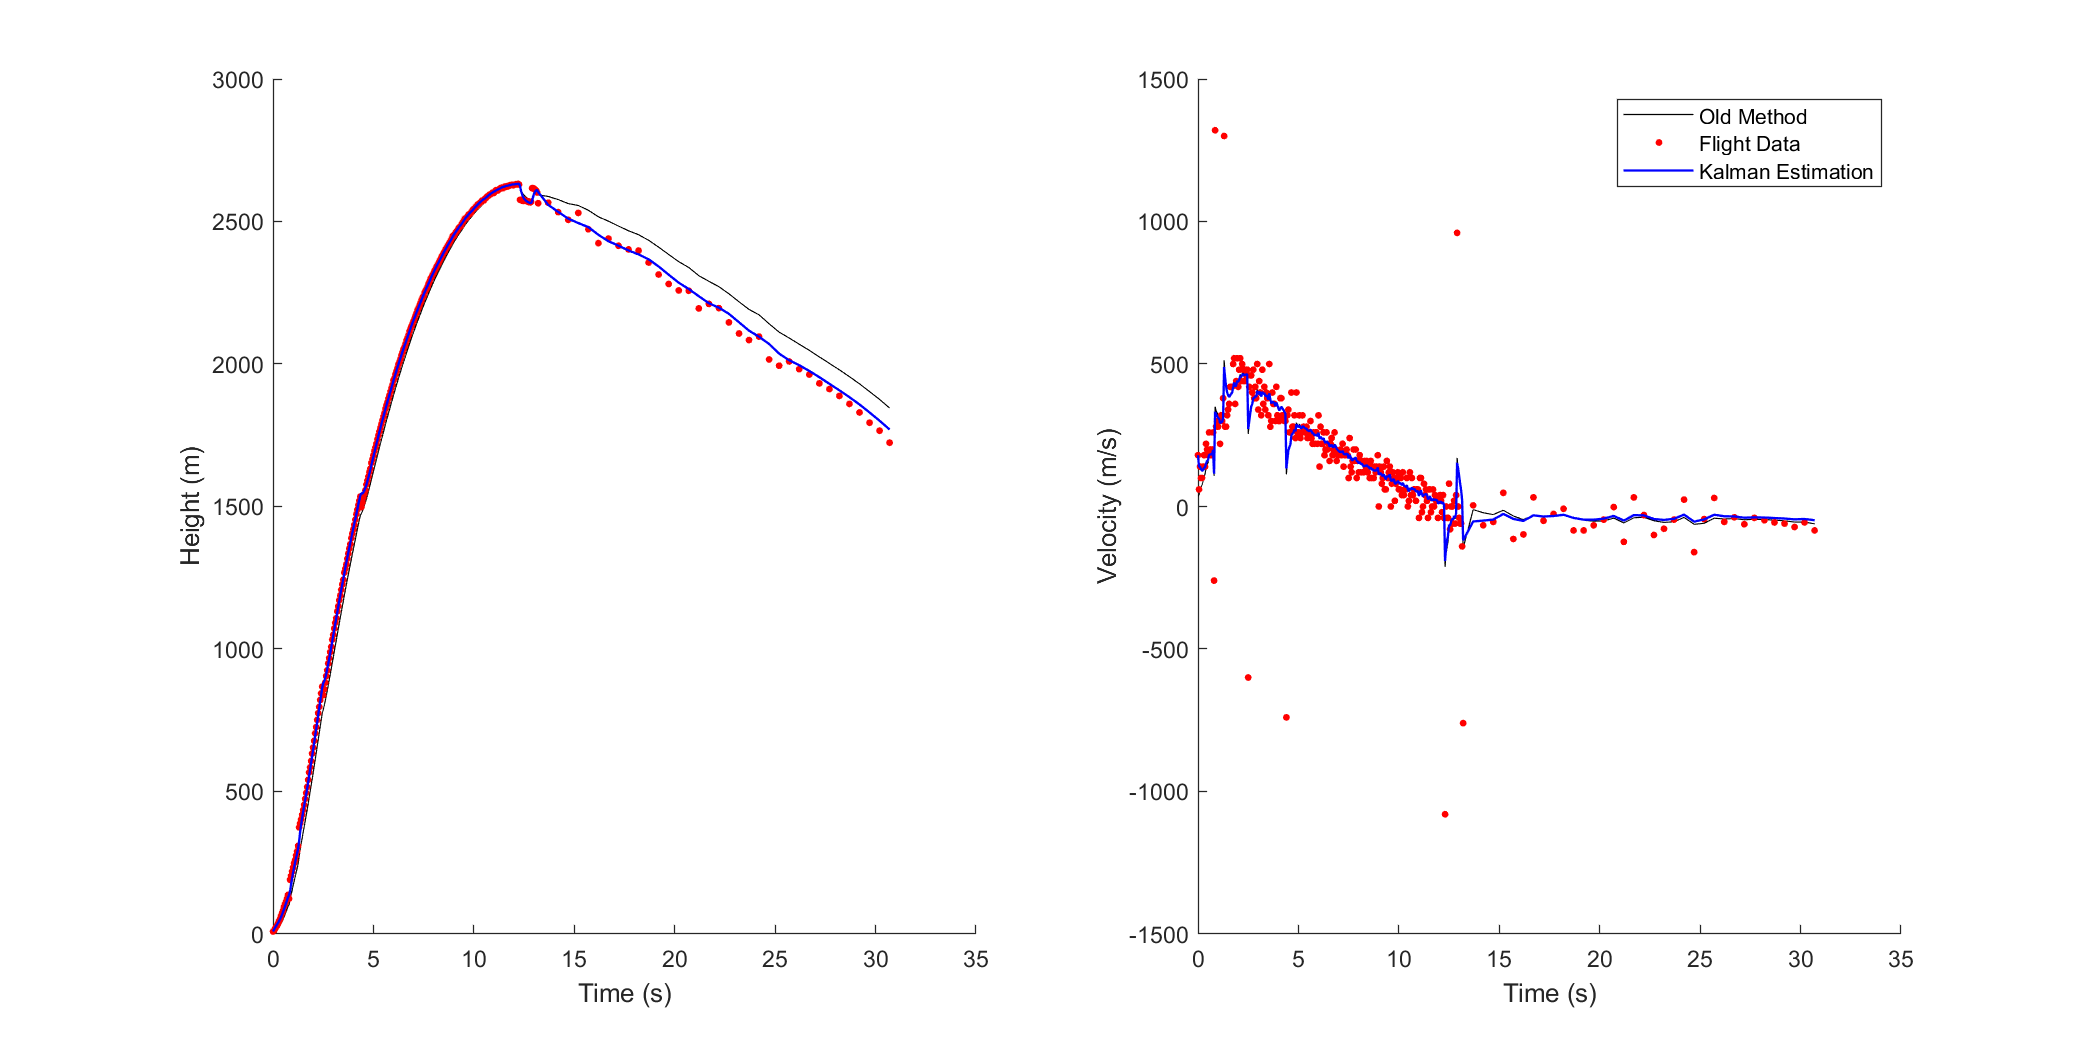


plot_res2(test_data(t_start:t_max,1), test_data(t_start:t_max,2:3), test_data(t_start:t_max,4:5), kalman_state)